# Tuning ottimale controllore PID - joint 1

### Caricamento modelli dei processi

clear all; clc; close all

Aggiungo opzione per evitare la molteplicità di 360° nella base.

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

 Carico il modello.

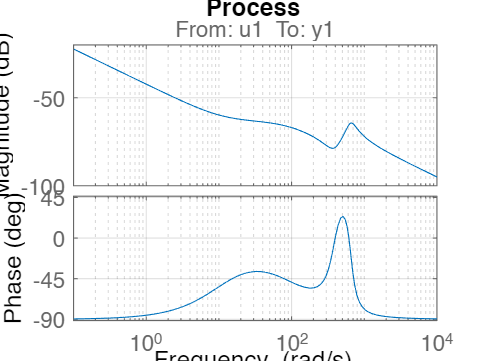

load modello_j1.mat

process = modello_continuo_tf_j1;
figure
bodeplot(process)
grid on; title('Process');

Scelta dell'intervallo di frequenze d'interesse

w_inf = 1;
w_sup = 10^4;

#### Inner loop: output Filtered **P **


$$C_2(s)=K_p \cdot \frac{1}{T_{fu}s+1}$$


Cifra di merito da minimizzare:


$$J=\left( \omega_c - \omega_{c,des}\right)^2$$


- $\omega_c$: frequenza (pulsazione) di taglio

- $\omega_{c,des}$: valore desiderato

Le incognite del problema sono $x=[K_p, \; K_i, \; K_d, \; T_{fd}, \; T_{fu}]$ (alcune verranno forzate a 0, se non vogliamo utilizzarle).

external_joint1.wc_des = 200;    % pulsazione di taglio desiderata

% funzione che restituisce il valore di J in funzione di x
J = @(x)pid_filt_cost_function(x,process,external_joint1.wc_des);

#### Vincoli

- Massima sensitività $MS$ per garantire la robustezza (1.4 molto robusto, 2 poco robusto ma aggressivo)

- La funzione di anello chiuso $F$ deve avere modulo limitato per $\omega\geq\omega_h$

- La funzione fra disturbo sul carico e l'uscita deve modulo limitato per $\omega\leq\omega_l$

- Il margine di fase deve essere almeno 60°

Definizione dei vincoli

% Massima sensitività
external_joint1.MS = 2;

% Reiezione disturbo di misura
external_joint1.wh = 2000;
external_joint1.Fh_max = 0.1;

% Reiezione disturbo sul carico
external_joint1.wl = 10;
external_joint1.Dl_max = 0.1;

% Minimo margine di fase tollerabile
external_joint1.PM_min = 60;

Per calcolare in maniera corretta $MS$ passo alla funzione anche il vettore delle pulsazioni naturali che voglio testare.

w_vector = logspace(log10(w_inf),log10(w_sup))';
w_vector = sort(unique([w_vector;external_joint1.wl;external_joint1.wh]));

Funzione per vincoli non lineari

nlcon = @(x)pid_filt_constraints(x, process, w_vector, ...
                                 external_joint1.MS, external_joint1.wh, external_joint1.Fh_max, ...
                                 external_joint1.wl, external_joint1.Dl_max, external_joint1.PM_min);

### Ottimizzatore interno

timeout = 60*2;
% [valore iniziale, limite inferiore, limite superiore]
external_joint1.aKp = [500, 100, 10000];
external_joint1.aKi = [0, 0, 0];
external_joint1.aKd = [0, 0, 0];
external_joint1.aTfd = [0, 0, 0];
external_joint1.aTfu = [1/70, 1/100, 1/40];

x0 = [external_joint1.aKp(1), external_joint1.aKi(1), external_joint1.aKd(1), external_joint1.aTfd(1), external_joint1.aTfu(1)];
    
problem = createOptimProblem('fmincon','x0',x0, ...
                                 'objective',J, ...
                                 'lb',[external_joint1.aKp(2), external_joint1.aKi(2), external_joint1.aKd(2), external_joint1.aTfd(2), external_joint1.aTfu(2)], ...
                                 'ub',[external_joint1.aKp(3), external_joint1.aKi(3), external_joint1.aKd(3), external_joint1.aTfd(3), external_joint1.aTfu(3)], ...
                                 'nonlcon',nlcon);

solver = GlobalSearch('Display','iter','MaxTime',timeout);
x = run(solver,problem)

 Num Pts                 Best       Current    Threshold        Local        Local                 
Analyzed  F-count        f(x)       Penalty      Penalty         f(x)     exitflag        Procedure
       0      150   2.973e-10                               2.973e-10            2    Initial Point
     200     1448   2.973e-10                               7.485e-10            2    Stage 1 Local
     300     1551   2.973e-10         998.4        1.074                              Stage 2 Search
     400     1651   2.973e-10          4161        1.162                              Stage 2 Search
     500     1751   2.973e-10     3.489e+04         0.44                              Stage 2 Search
     600     1851   2.973e-10        0.1029       0.1029                              Stage 2 Search
     700     1951   2.973e-10     3.133e-05    3.133e-05                              Stage 2 Search
     795     2052   2.973e-10       0.02183       0.2092         1653           -1    Stage 2 L

x = 	1.0e+03 *

    9.3613         0         0         0    0.0000


% solver = MultiStart('Display','iter','MaxTime',timeout,'UseParallel',true);
% addAttachedFiles(gcp,["pid_filt_constraints.m" "pid_filt_cost_function.m"]) % Usare se si abilita il pool parallelo su un Cluster online
% n_startingPoints = 50;
% x = run(solver,problem,n_startingPoints)

s=tf('s');
Kp = x(1);
Tfu = x(5);
Cv_joint1 = Kp*1/(Tfu*s+1);
Cv_joint1.InputName = 'sp-vel';
Cv_joint1.OutputName = 'torque';

Loop_int_joint1 = process*Cv_joint1;

figure;
subplot(1,2,1)
margin(Loop_int_joint1)
grid on;

subplot(1,2,2)
bodemag(feedback(1,Loop_int_joint1))
title('Sensitivity Function')
getPeakGain(feedback(1,Loop_int_joint1))

ans = 1.5341

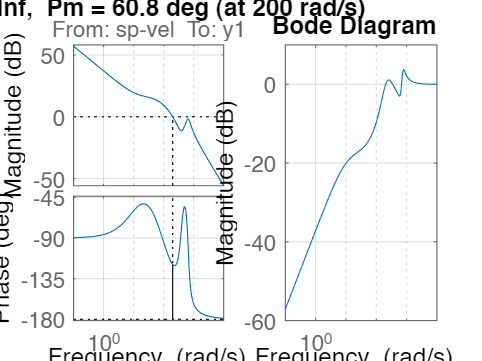

grid on

### Loop esterno: PI

Processo da controllare (velocità → posizione) visto dal controllore esterno: serie tra la funzione di anello chiuso del loop interno e l'integratore (necessario per passare da velocità a posizione).


$$P_{\mathrm{ext}} =\frac{C_v \cdot P}{1+C_v \cdot P}\cdot \frac{1}{s}$$


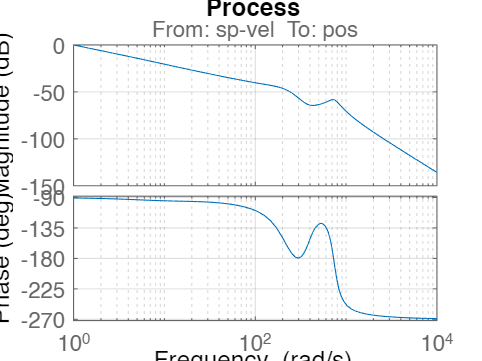

process_ext = minreal(feedback(Cv_joint1*process,1)*1/s);
process_ext.InputName = 'sp-vel';
process_ext.OutputName = 'pos';
figure
bodeplot(process_ext)
grid on; title('Process');

external_joint1.wc_des = 200;    % pulsazione di taglio desiderata

% funzione che restituisce il valore di J in funzione di x
J = @(x)pid_filt_cost_function(x,process_ext,external_joint1.wc_des);

### Vincoli

Definizione dei vincoli

% Massima sensitività
external_joint1.MS = 1.6;

% Reiezione disturbo di misura
external_joint1.wh = 2000;
external_joint1.Fh_max = 0.1;

% Reiezione disturbo sul carico
external_joint1.wl = 10;
external_joint1.Dl_max = 0.1;

% Minimo margine di fase tollerabile
external_joint1.PM_min = 60;

w_vector = logspace(log10(w_inf),log10(w_sup))';
w_vector = sort(unique([w_vector;external_joint1.wl;external_joint1.wh]));

nlcon = @(x)pid_filt_constraints(x, process_ext, w_vector, ...
                                 external_joint1.MS, external_joint1.wh, external_joint1.Fh_max, ...
                                 external_joint1.wl, external_joint1.Dl_max, external_joint1.PM_min);

### Ottimizzatore esterno

timeout = 60*2;
% [valore iniziale, limite inferiore, limite superiore]
external_joint1.aKp = [1, 0.01, 100];
external_joint1.aKi = [0.01, 0.0001, 100];
external_joint1.aKd = [0.001, 0.0001, 10];
external_joint1.aTfd = [10, 0.01, 100];
external_joint1.aTfu = [0, 0, 0];

x0 = [external_joint1.aKp(1), external_joint1.aKi(1), external_joint1.aKd(1), external_joint1.aTfd(1), external_joint1.aTfu(1)];
    
problem = createOptimProblem('fmincon','x0',x0, ...
                                 'objective',J, ...
                                 'lb',[external_joint1.aKp(2), external_joint1.aKi(2), external_joint1.aKd(2), external_joint1.aTfd(2), external_joint1.aTfu(2)], ...
                                 'ub',[external_joint1.aKp(3), external_joint1.aKi(3), external_joint1.aKd(3), external_joint1.aTfd(3), external_joint1.aTfu(3)], ...
                                 'nonlcon',nlcon);

solver = GlobalSearch('Display','iter','MaxTime',timeout);
x = run(solver,problem)

 Num Pts                 Best       Current    Threshold        Local        Local                 
Analyzed  F-count        f(x)       Penalty      Penalty         f(x)     exitflag        Procedure
       0     1587       968.6                                   968.6            2    Initial Point

GlobalSearch stopped because maximum time is exceeded.

GlobalSearch called the local solver once before exceeding 
the clock time limit (MaxTime = 120 seconds).
1 local solver run converged with a positive local solver exit flag.


x =     9.6028    0.0001    1.7763    0.0100         0


% solver = MultiStart('Display','iter','MaxTime',timeout,'UseParallel',true);
% addAttachedFiles(gcp,["pid_filt_constraints.m" "pid_filt_cost_function.m"]) % Usare se si abilita il pool parallelo su un Cluster online
% n_startingPoints = 50;
% x = run(solver,problem,n_startingPoints)